%root to take (original signals) from 
rootttf ='C:\Users\Lyriss\Desktop\nwhales\output3\';
%root to save new signals to 
roottst ='C:\Users\Lyriss\Desktop\nwhales\temp\';
%i for file index with given name and n for getting n variations of
%signal#i
for i=1:1:81

i = 1

 for n=1:1:81

n = 1

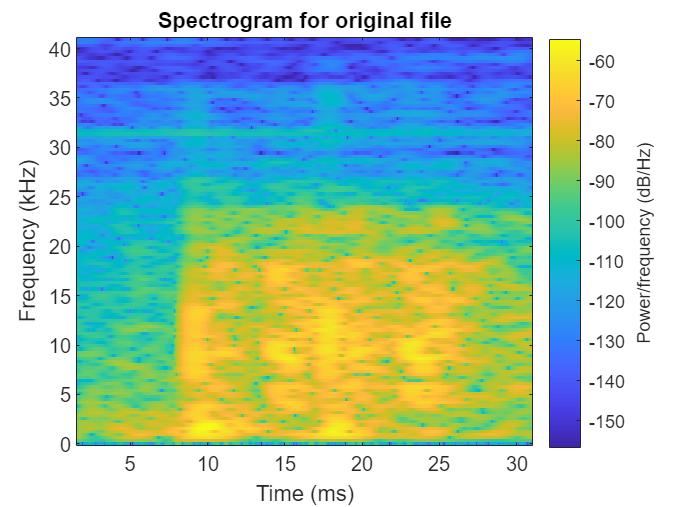

        %open files
        filename= sprintf('chunk%d.wav',i);
        fullname = strcat(rootttf, filename);
        [audio1, fs1] = audioread(fullname);
        figure
        spectrogram(audio1, hann(256, "periodic"), 250, 256, fs1, 'yaxis');
        title('Spectrogram for original file');

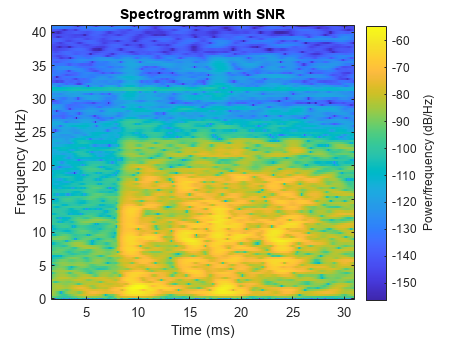




        %%%% speed
        r_in_1=0+(3-0).*rand(1,1);
        r_in_1f=round(r_in_1);
        if r_in_1f==1
            r=0.8+(1.2-0.8).*rand(1,1); %N random numbers in the interval (a,b) with the formula r = a + (b-a).*rand(N,1).
            audio1 = stretchAudio(audio1,r);
            figure
            spectrogram(audio1, hann(256, "periodic"), 250, 256, fs1, 'yaxis');
            title('Speed  up spectrogram');
        end
        %%%% pitch
      r_in_2=0+(3-0).*rand(1,1);
        r_in_2f=round(r_in_2);
        if r_in_2f==1
            r2=-3+(3-(-3)).*rand(1,1);
            r2_fin=round(r2);  
            audio1 = shiftPitch(audio1,r2_fin);
            figure
            spectrogram(audio1, hann(256, "periodic"), 250, 256, fs1, 'yaxis');
            title('Pitch shift spectrogram');
        end
        %%%% +-3db
        r_in_3=0+(3-0).*rand(1,1);
        r_in_3f=round(r_in_3);
        if r_in_3f==1
            r3=-3+(3-(-3)).*rand(1,1);
            r3_fin=round(r3);
            audio1=audio1*db2mag(r3_fin);
            spectrogram(audio1, hann(256, "periodic"), 250, 256, fs1, 'yaxis');
            title('Spectrogramm with volume increase');
        end
        %%%% SNR
        r_in_4=0+(3-0).*rand(1,1);
        r_in_4f=round(r_in_4);
        if r_in_4f==1
            r4=50+(100-50).*rand(1,1);
            audio1 = awgn(audio1,r4,'measured', 'db');
            spectrogram(audio1, hann(256, "periodic"), 250, 256, fs1, 'yaxis');
            title('Spectrogramm with SNR');
        end

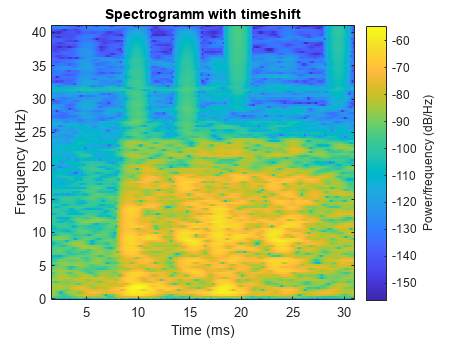

        %%%% timeshift
        r_in_5=0+(3-0).*rand(1,1);
        r_in_5f=round(r_in_5);
        len_audio1 = numel(audio1);
        if r_in_5f==1
            for gg=10:100:len_audio1
            r5=-4+(4-(-4)).*rand(1,1);
            r5_fin=round(r5);
            temp=audio1(gg);
            audio1(gg)=audio1(gg+r5_fin);
            audio1(gg+r5_fin)=temp;
            end
            spectrogram(audio1, hann(256, "periodic"), 250, 256, fs1, 'yaxis');
            title('Spectrogramm with timeshift');
        end

        filenameENDRES=sprintf('classic_chunk_%d_%d.wav', i,n);
        fullfilenameENDRES=strcat(roottst,filenameENDRES);
        audiowrite(fullfilenameENDRES, audio1, fs1);
 end
end
